# Esercitazione ONLINE n.2, CN, CdS Informatica, prof. Giulio Giunta

## Problema e metodo del punto fisso

Il problema del punto fisso $g(x)=x$ consiste nel trovare un punto $p$ del dominio della funzione $g$ in cui la funzione assume un valore $g(p)$ uguale a quello del punto di valutazione, cioè $p=g(p)$. Il problema può non ammettere soluzione, oppure ammettere una o più soluzioni. Dal punto di vista grafico, la soluzione del problema è l'ascissa del punto di intersezione (se esiste), o dei punti di intersezione, del grafico di $g$ con la bisettrice del primo quadrante, che è il luogo dei punti caratterizzati dall'avere ascissa uguale all'ordinata.

Il problema del punto fisso può essere risolto dal metodo del punto fisso $x_{k+1}=g(x_k)$, che converge al punto fisso $p$ se $g$ è una contrazione in un intervallo che contiene $p$, oppure, nel caso $g$ sia derivabile, se $|g'(p)|<1$

Consideriamo per esempio il problema di punto fisso $\sqrt{x+1}=x$, per cui $g(x)=\sqrt{x+1}$. Esaminiamo graficamente il metodo del punto fisso. Il grafico della funzione $g$ è in blu. La bisettrice del primo quadrante è in rosso. L'approssimazione iniziale è 0.5 ed è riportata in blu sulle ascisse insieme alle successive quattro approssimazioni

clf
format long
g = @(x) sqrt(x+1);
figure(1)
fplot(g,[0,1.7],'linewidth',3),grid on
hold on
plot([0 1.7],[0 1.7],'r','linewidth',3) 
x = 0.5; y = g(x);
for k = 1:5
  plot(x,0,'.b',[x y],[y y],'-g','linewidth',2,'markersize',18)
  x = y;
  y = g(x); plot([x x],[x y],'-m','linewidth',2)
end
fprintf('dopo %d iterazioni \n approssimazione = %0.6g',k,y)

dopo 5 iterazioni 
 approssimazione = 1.61686

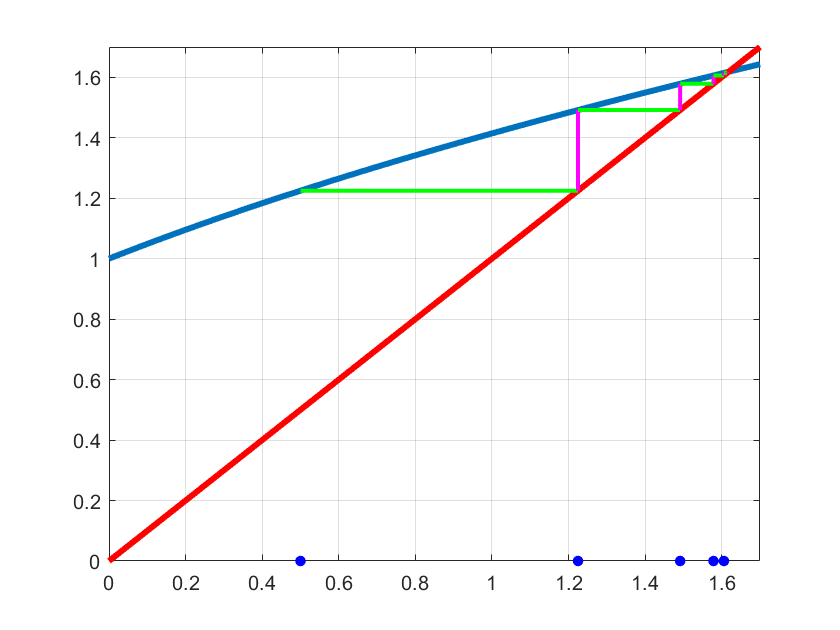

p = y;
hold off

Si noti che il valore della derivata della funzione $g$ calcolata nella soluzione è minore di 1, e quindi il metodo converge, come si vede dal grafico

 gprimo = @(x) 1./(2*sqrt(x + 1));
 gprimo(p)

ans =    0.309086292532575


La convergenza è lineare perché $g'(p) \ne 0$;  il residuo dell'approssimazione, dopo 5 iterazioni, è

 abs(g(p)-p)

ans =      8.110434517674125e-04


Il problema del punto fisso è mal condizionato in un punto fisso $p$ quando il grafico della funzione $g$ ha una pendenza circa uguale a 1 vicino a $p$. L'indice di condizionamento è dato da $k_g=\left| \frac {1}{g'(p)-1} \right|$ . Si noti che se $g'(p)=1$ l'indice di condizionamento è $\infty$ e il problema potrebbe avere infinite soluzioni.

Consideriamo il problema di punto fisso $2(2-e^{-x})=x$

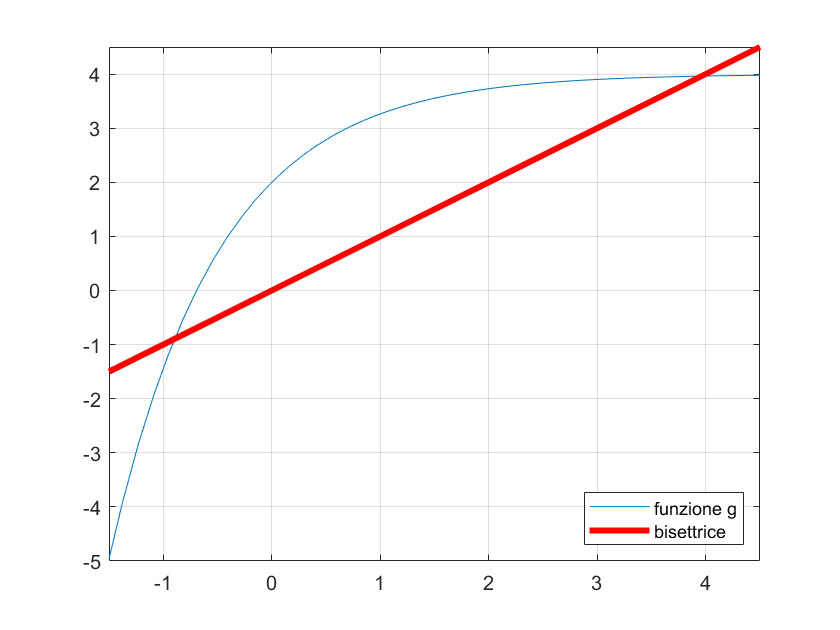

g1 = @(x) 2*(2-exp(-x));
figure(2)
fplot(g1,[-1.5, 4.5])
hold on
plot([-1.5 4.5],[-1.5 4.5],'r','linewidth',3) 
legend('funzione g','bisettrice','location','southeast')
grid on
hold off

La funzione ha due punti fissi. Consideriamo il secondo punto fisso $p_2$ e approssimiamolo con 7 cifre corrette della parte frazionaria (accuratezza richiesta $10^{-7}$ ), usando la function `PFisso` della collezione dei programmi Matlab sviluppati nel Corso, facendo visualizzare le approssimazioni a ogni iterazione, insieme con la differenza tra approssimazione corrente e approssimazione precedente

delta_ass = 1e-7;
xiniz = 3;
p2 = PFisso(g1,xiniz,delta_ass,30)

     3

   3.900425863264272   0.900425863264272

   3.959533414010816   0.059107550746544

   3.961855978101966   0.002322564091151

   3.961944467236897   0.000088489134931

   3.961947834589081   0.000003367352184

   3.961947962723908   0.000000128134827

   3.961947967599699   0.000000004875791



p2 =    3.961947967599699


Calcoliamo il residuo

residuop2 = abs(p2-g1(p2))

residuop2 =      1.855338105372084e-10


Si noti che, dall'esame del grafico, il punto fisso $p_2$ è ben condizionato e quindi il residuo è una buona stima dell'errore assoluto.

Approssimiamo il primo punto fisso $p_1$

xiniz = -1;
p1 = PFisso(g1,xiniz,delta_ass,30)

    -1

  -1.436563656918091   0.436563656918091

  -4.412433899101432   2.975870242183341

   1.0e+02 *

  -1.609398859038117   1.565274520047103

   1.0e+70 *

  -1.571572286785588   1.571572286785588

  -Inf   Inf



p1 =   -Inf


Il metodo diverge. Proviamo a cambiare l'approssimazione iniziale

xiniz = 0;
p1 = PFisso(g1,xiniz,delta_ass,30)

     0

     2     2

   3.729329433526774   1.729329433526774

   3.951982139952946   0.222652706426172

   3.961566851877137   0.009584711924191

   3.961933462793616   0.000366610916479

   3.961947415843881   0.000013953050266

   3.961947946789797   0.000000530945915

   3.961947966993374   0.000000020203577



p1 =    3.961947966993374


Il metodo converge, ma al secondo punto fisso.

Questo comportamento è in accordo con il teorema della convergenza del metodo del punto fisso. Infatti, calcoliamo la derivata della funzione e valutiamola in due punti vicini ai due punti fissi

g1primo = @(x) 2*exp(-x);
g1primo(p2)

ans =    0.038052032214767


La derivata in $p_2$ è minore di 1 e quindi il metdodo converge; la convergenza è rapida perché la derivata è vicina a 0.

Abbiamo la necessità di calcolare il valore del primo punto fisso $p_1$ con un metodo diverso dal metodo del punto fisso.

Calcoliamo  $p_1$ risolvendo  $2(2-e^{-x})-x =0$

p1 = fzero(@(x) 2*(2-exp(-x))-x,[-1,0])

p1 =   -0.895084321275231


residuop1 = abs(g1(p1)-p1)

residuop1 =      8.881784197001252e-16


Calcoliamo ora la derivata di $g$ in $p_1$

g1primo(p1)

ans =    4.895084321275230


che è maggiore di 1. Osservazione: il problema del punto fisso per $p_1$ è ben condizionato e infatti siamo riusciti a calcolare una sua approssimazione con altissima accuratezza. Tuttavia il metodo del punto fisso non converge. Questo ci conferma che il condizionamento di un problema e l'efficacia di un algoritmo risolutore sono due diverse problematiche.

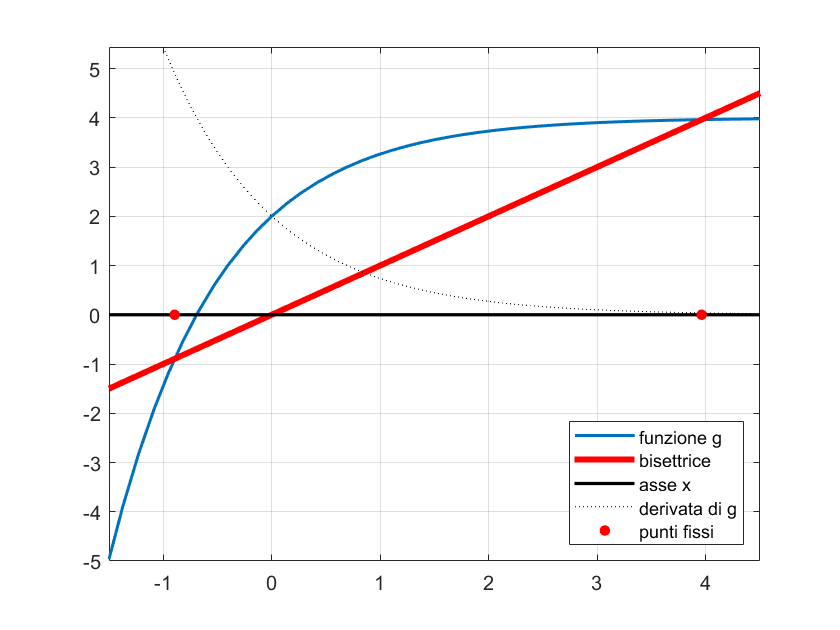

figure(3)
fplot(g1,[-1.5, 4.5],'LineWidth',1.5)
hold on
plot([-1.5 4.5],[-1.5 4.5],'r','linewidth',3) 
grid on
plot([-1.5 4.5],[0 0],'k','linewidth',1.6) 
fplot(g1primo,[-1, 4.5],':k')
plot([p1 p2],[0 0],'.r','markersize',18)
legend('funzione g','bisettrice','asse x','derivata di g','punti fissi','location','southeast')
hold off

### Problema del punto fisso e problema f(x)=0

Un problema $f(x)=0$ può sempre essere trasformato (in infiniti modi) in un problema equivalente (cioè, che ha la stessa soluzione) di punto fisso.

Consideriamo il problema $2(1-e^{-x})-x=0$. 

f = @(x) 2*(1-exp(-x))-x;
figure(4)
fplot(f,[-0.2,2],'g','linewidth',1.8)
hold on
plot([-0.2,2],[0 0],'k')

Calcoliamo le due soluzioni con `fzero`

rf1 = fzero(f,[-0.2,0.2])

rf1 =      1.486528216688045e-17


rf2 = fzero(f,[1.5,2]) 

rf2 =    1.593624260040040


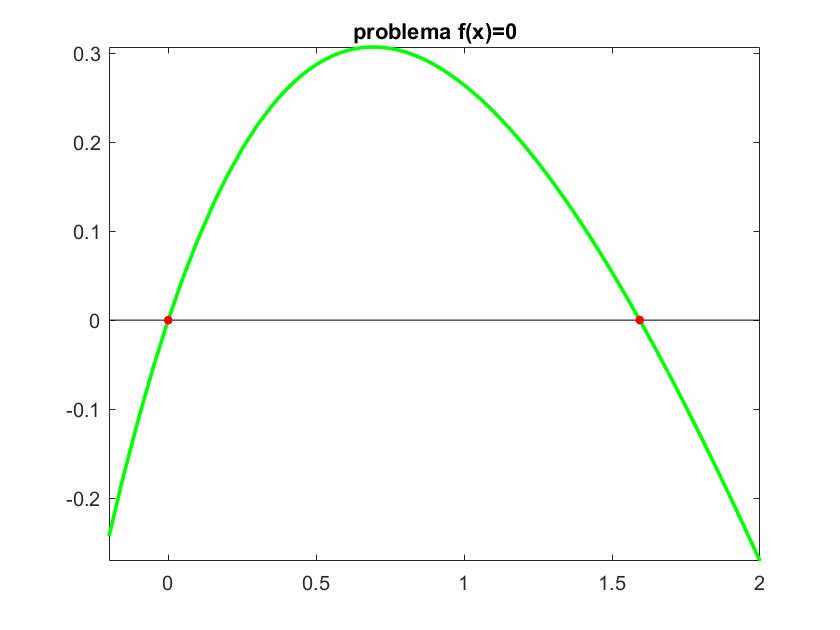


plot([rf1, rf2],[0,0],'.r','markersize',15)
title('problema f(x)=0')
hold off

Un problema di punto fisso equivalente è   $2(1-e^{-x})=x$ 

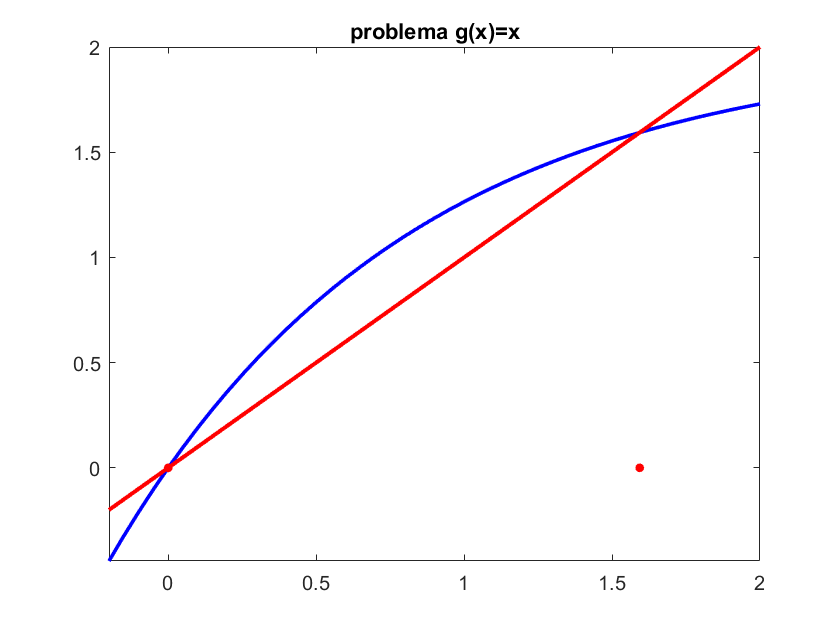

g = @(x) 2*(1-exp(-x));
figure(5)
fplot(g,[-0.2,2],'b','linewidth',1.8)
hold on
plot([-0.2,2],[-0.2,2],'r','LineWidth',2)
plot([rf1, rf2],[0,0],'.r','markersize',15)
title('problema g(x)=x')
hold off

Risolviamo il problema di punto fisso $2(1-e^{-x})=x$  con la `PFisso `con 5 cifre della parte frazionaria corrette. La `PFisso` deve ssere richiamata 2 volte, una per ogni punto fisso

p1 = PFisso (g,-0.2,1e-5,30)

  -0.200000000000000

  -0.442805516320340   0.242805516320340

  -1.114138960581270   0.671333444260930

  -4.093887021807771   2.979748061226501

   1.0e+02 *

  -1.179451077089589   1.138512206871511

   1.0e+51 *

  -3.341484424815221   3.341484424815221

  -Inf   Inf



p1 =   -Inf


Il metodo del piunto fisso diverge per il primo punto fisso.

p2 = PFisso (g,1.5,1e-5,30)

   1.500000000000000

   1.553739679703140   0.053739679703140

   1.577088566591492   0.023348886888352

   1.586848690393651   0.009760123802159

   1.590861483789419   0.004012793395768

   1.592499982448263   0.001638498658844

   1.593167123975996   0.000667141527733

   1.593438448566425   0.000271324590428

   1.593548743749277   0.000110295182852

   1.593593570892752   0.000044827143474

   1.593611788523733   0.000018217630981

   1.593619191886769   0.000007403363036



p2 =    1.593619191886769


Si noti che il metodo di punto fisso non converge sul primo punto fisso, perché $|g'(0)|=2e^{-0}>1$, mentre converge sul secondo punto, perché $|g'(1.593)|=2e^{-1.593}<1$

  gprimo = @(x)  2*exp(-x);
  gprimo(0)

ans =      2


  gprimo(p2)

ans =    0.406377799539715


 Calcoliamo residuo ed errore per il secondo punto fisso, che è ben condizionato

residuop2 = abs(g(p2)-p2)

residuop2 =      3.008573516538604e-06


errorep2 = abs(p2-rf2)

errorep2 =      5.068153271725606e-06


#### Considerazioni su punto fisso per f(x)=0

Consideriamo il problema $x^2-x-2=0$. Tale problema può essere trasformato in tre problemi di punto fisso equivalenti. Consideriamo le tre funzioni di iterazione dei tre problemi di punto 


$$g_1(x)=x^2-2$$



$$g_2(x)=1+\frac{2}{x}$$



$$g_3(x)=\frac{x^2+2}{2x-1}$$


che sono equivalenti rispetto al problema $f(x)=0$, nel senso che

$g_1(x)=x$ , $g_2(x)=x$, $g_3(x)=x$ ,  $x^2-x-2=0$

hanno tutti la stessa soluzione $p=2$.

Definiamo le tre function che implementano le tre funzioni di iterazione 

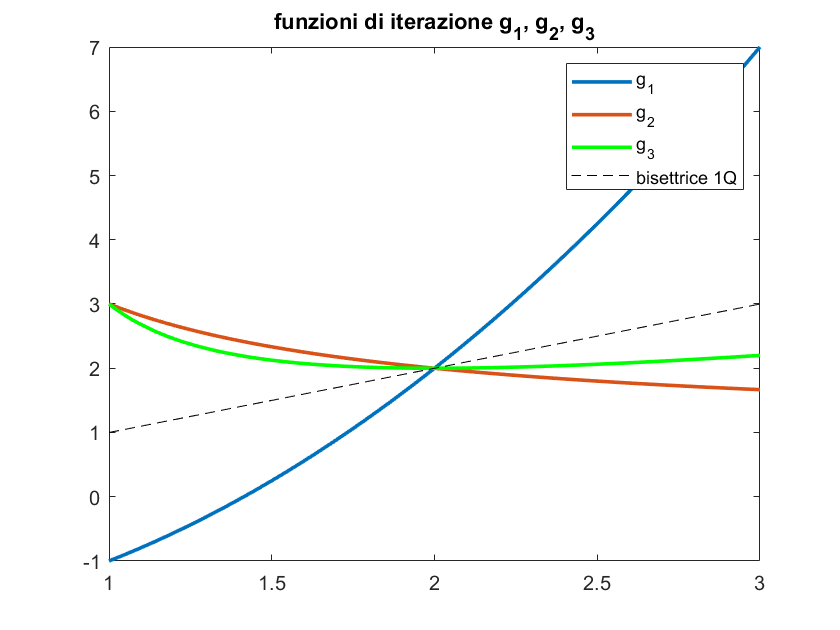

g1 = @(x) x.^2-2;
g2 = @(x) 1+2./x;
g3 = @(x) (x.^2+2)./(2*x-1);
fplot(g1,[1 3],'linewidth',1.8)
hold on
fplot(g2,[1 3],'linewidth',1.8)
fplot(g3,[1 3],'g','linewidth',1.8)
plot([1 3],[1 3],'--k')
legend('g_1','g_2','g_3','bisettrice 1Q')
title('funzioni di iterazione g_1, g_2, g_3')
hold off

Si noti che l'equivalenza dei tre problemi di punto fisso è confermata dal fatto che i grafici di $g_1$, $g_2$ e $g_3$ intersecano la bisettrice del primo quadrante nello stesso punto. 

Per analizzare la convergenza del metodo del punto fisso applicato alle tre diverse funzioni di iterazione, si possono calcolare le loro derivate, in quanto le tre funzioni sono derivabili nell'intervallo considerato


$$g_1'(x)=2x$$



$$g_2'(x)=-\frac{2}{x^2}$$



$$g_3'(x)=\frac{2x(2x-1)-2(x^2+2)}{(2x-1)^2}$$


g1primo = @(x) 2*x;
g2primo = @(x) -2./x.^2;
g3primo = @(x) (2*x.*(2*x-1)-2*(x.^2+2))./(2*x-1.^2);
figure(2)
fplot(g1primo,[1 3])
hold on
fplot(g2primo,[1 3])
fplot(g3primo,[1 3],'g')
grid on
title('derivate di g_1,g_2, g_3')
fprintf('derivata di g1 in 2 = %4.2f',g1primo(2))

derivata di g1 in 2 = 4.00

fprintf('derivata di g2 in 2 = %4.2f',g2primo(2))

derivata di g2 in 2 = -0.50

fprintf('derivata di g3 in 2 = %4.2f',g3primo(2))

derivata di g3 in 2 = 0.00

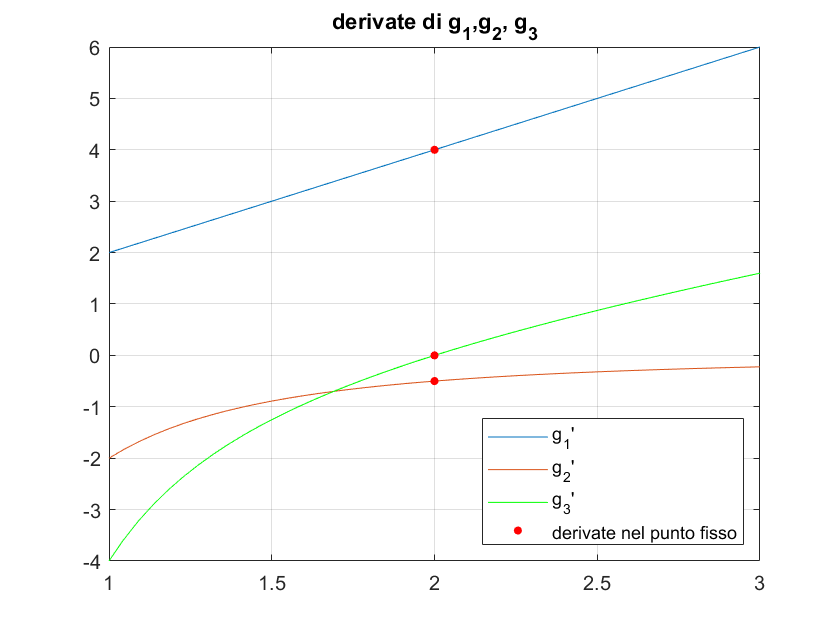

plot([2,2,2],[g1primo(2),g2primo(2),g3primo(2)],'.r','markersize',14)
legend('g_1''','g_2''','g_3''','derivate nel punto fisso','location','southeast')
hold off

Poiché $|g_1'(2)|=4  >1$, il metodo del punto fisso NON converge se applicato a $g_1(x)$. Poiché $|g_2'(2)|=0.5 <1$ e $|g'_3(2)|=0  <1$, il metodo del punto fisso converge se applicato a $g_2(x)$e a $g_3(x)$, ma la convergenza è lineare nel caso di $g_2(x)$, mentre è quadratica nel caso di $g_3(x)$.

Il seguente esperimento evidenzia la diversa velocità di convergenza per $g_2(x)$  e $g_3(x)$ del metodo del punto fisso in `PFisso`. Per l'esperimento usiamo una variante di `PFisso`, chiamata `PFissoIT`, che restituisce anche il numero di iterazioni effettate dal metodo.

[p2, niter2] = PFissoIT(g2,10,1e-5,100)

p2 =    2.000002080745406


niter2 =     21


[p3, niter3] = PFissoIT(g3,10,1e-5,100)

p3 =      2


niter3 =      8
